# 付録：周波数スイープによるSimscapeモデルに対する伝達関数推定

Scrpit04でははステップ応答で周波数特性の変化を観測したが、ボード線図上でその特性の違いを確認したい。

Simulinkでモデリングされた数式モデルはScript03で示されたような線形化によって伝達関数を取得することができる。

一方でSimscapeは電気回路モデルであるため、数式としてモデリングされていないため、別の手法が必要になる。

これはシミュレータの回路定式化の手法がSimulikとSimscapeで異なっているためである。

これまで述べてきたように状態平均化法によってSimulinkのモデルはPWM1周期分の振る舞いが平均化されて

「微分方程式としてモデリング」されるため、定常状態近傍での偏微分演算が可能になるため、線形化が可能である。

一方　Simscape側ではデバイスのPWMスイッチングの振る舞いを精度良く表現できるように、修正接点解析法を用いている。

PWMによって時間的にONとOFFを繰り返す非線形なモデルは偏微分によって線形化できないため、

外部から正弦波信号を入力した際の出力応答の振幅、および位相変化に基づいて「周波数特性を推定する」という手法を用いる。

## パラメータの設定

パラメータは下記のように設定する。

Simscape側には直流抵抗成分 ESRやインダクタンスの直流抵抗成分などの要素を追加してモデリングしてみたので

そのパラメータも含まれている。

clear variables
open_system("Model\Script04_Model\Diff_Simulink_SimscapeModel.slx");

C1 = 300e-6;%[F]
esr = 1e-4;%[Ohm]

L1 = 200e-6;%[H]
l1r =1e-4; %[Ohm]

fsw = 20000;%{Hz]
Tsw = 1 / fsw;%[Sec]

HighVth = 10;
LowVth = 10;

Ro = 5;
Vin = 12;
Duty = 0.5;

## Simulink モデルのモデル操作点での周波数特性の推定

[https://jp.mathworks.com/help/slcontrol/ug/linearize-simulink-model.html](https://jp.mathworks.com/help/slcontrol/ug/linearize-simulink-model.html)

### **操作１：伝達関数における入力を指定する。**

１．Dutyが入力されている信号線を右クリックし右クリックメニューを開く

 2. 線形解析ポイントから入力の摂動を選択 

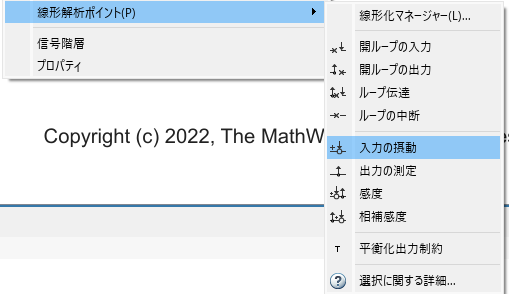

次に出力を指定する。

今回伝達関数の解析を行うのはVout（Vc)のみとする。

モデリングや条件を設定すればiLに対しての推定を行うこともできるが、

Simulinkモデリングの結果からもわかるように　電流のダイナミクスを示す式にはVcからのフィードバックが存在する。

そのため、Simscape回路で推定を行おうとするとDutyからの外乱とVout(Vc)からの両方の外乱の影響が混在して

電流波形に重畳するため、原理上影響の分離が難しくなるためである。

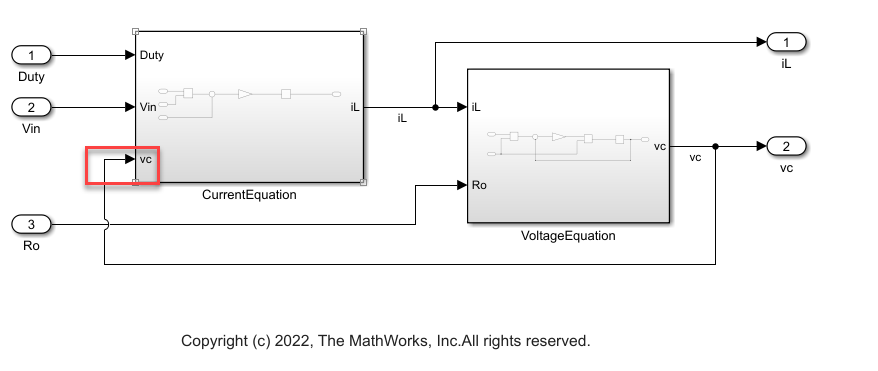

出力を指定する場合は同様に右クリックメニューから

１．信号解析ポイントを選択

２．”出力の測定”を選択

をおこなう。これをSimscape サブシステムの出力側のVout(Vc)に行う。

**＃注意：モデルの他の信号ににすでに解析ポイントが設定されている場合、結果が変化してしまうので一度モデルのすべての信号を調べて他に解析ポイントが設定されていないか確認する必要がある。**

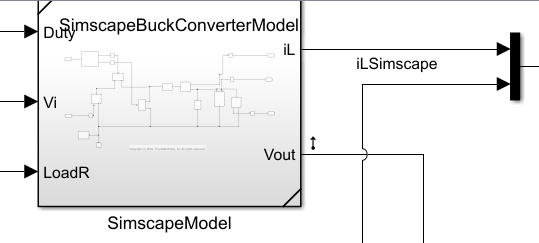

### **操作２：”Simulink Control Design”の”モデル線形器アプリを使う**

上部ツールストリップから

- ”アプリ”タブの選択

- モデル線形化器アプリをクリック

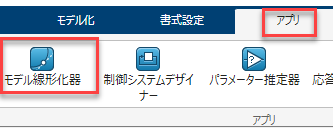

このようなウィンドウが開く。

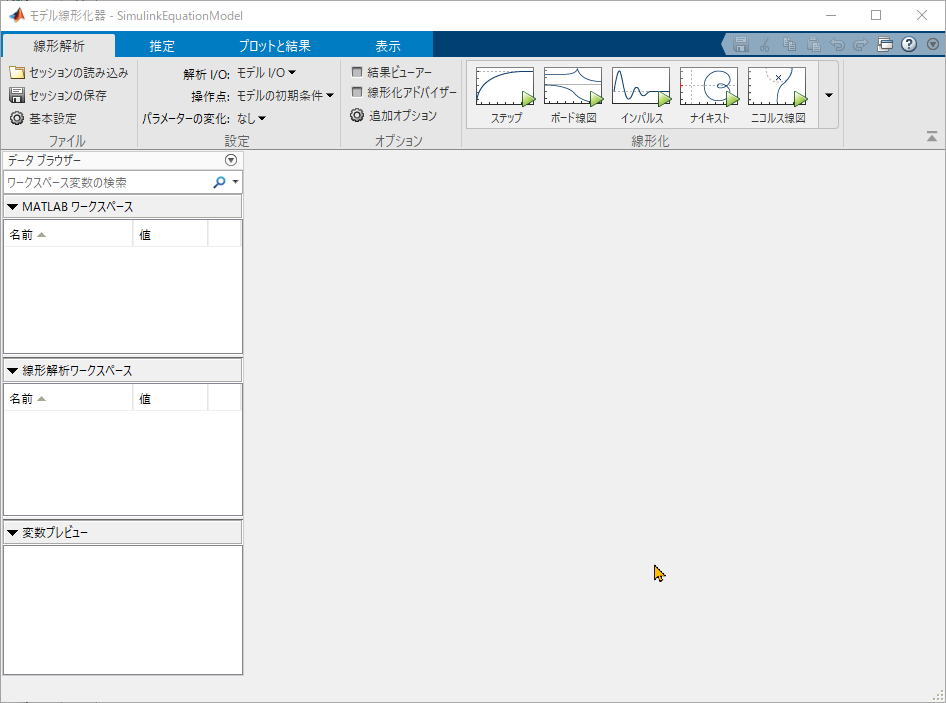

### **操作３：推定のための入力信号作成**

偏微分による線形化をではなく、外部から微小変動として正弦波信号を入力した際に

出力にはその微小変動に伴って出力値が変化する。

正弦波信号は常に一定の振幅・周波数で入力される。

その際に出力に現れる微小変動が、入力された正弦波信号に対してどの程度振幅が変化したかを調べることで、

入力された正弦波周波数におけるゲイン特性を推定することができる。

また、同様に入力された正弦波信号にたいしてどの程度位相が変化したかを調べることで

入力された正弦波周波数における位相特性を推定することができる。

このプロセスを入力される正弦波の周波数を更新しながら逐次繰り返すことで、

離散的な周波数特性データを取得することができる。

いまから行う操作はそのプロセスに必要な「複数の周波数を切り替えながら入力する正弦波信号」を

GUIの操作で簡単に作成する手順である。

１．モデル線形化器アプリの「推定」タブをクリック

２．画面左上部にある「入力信号：新規作成▼」をクリック

３．sinestremを選択

４．一般の周波数単位をHzにする（rad/sで周波数を指定したい場合は変更しなくても良いです）

５．開いたダイアログの「＋」ボタンを押して入力する信号データセットを作成する

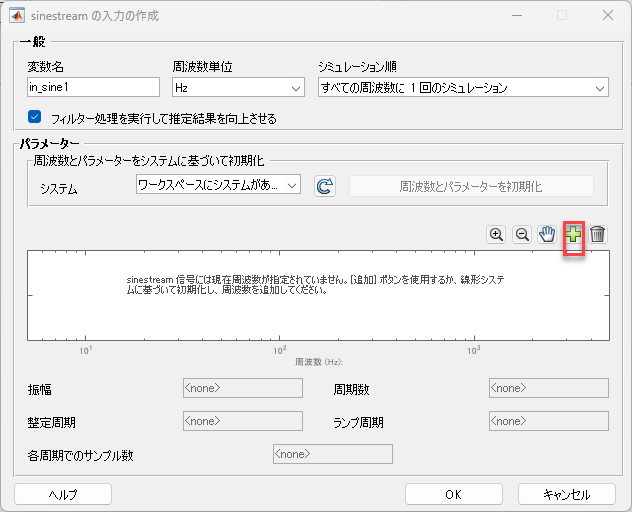

５．周波数の追加ダイアログで周波数の範囲、周波数の数を指定する。

下記のように設定した場合は100~10000Hzの間で30刻みでデータを作成することになります。

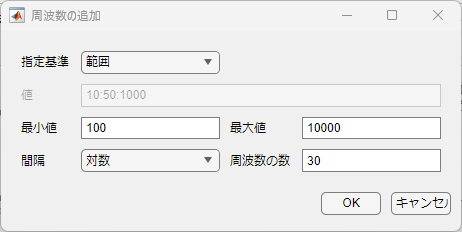

6.各データを下記のようにドラックして選択し、正弦波の振幅などの設定を行い「適応」をクリックする。

（今回は振幅0.01 周期数5 整定周期1 ランプ周期0　サンプル数50と設定します）

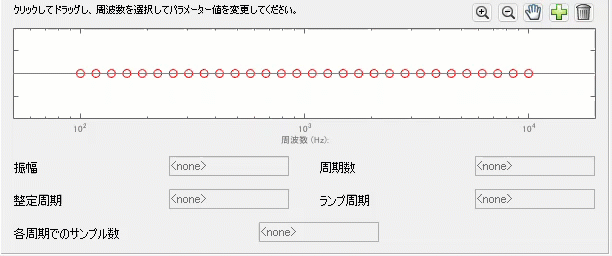

#### Hint:各パラメータの意味合い

対象となるコンバータの出力電力・電圧・電流などの仕様やスイッチング周波数などで

適切なパラメータは異なるため、コンバータの設計者であるユーザが適切なパラメータを選定する必要があります。

#### sinestream 入力信号　

[https://jp.mathworks.com/help/slcontrol/ug/creating-sinestream-input-signals.html](https://jp.mathworks.com/help/slcontrol/ug/creating-sinestream-input-signals.html)

上記ヘルプドキュメントの記載をご確認ください。図を含めての解説があるため大変わかりやすいです。

電源回路における補足情報を下記に示します。

**振幅：**

正弦波外乱の振幅を示します。今回の場合DutyからVoutまでの伝達関数を推定しようとしているため、Dutyに対して0.01の微小変化を重畳させることになります。

これが小さすぎるとDutyの変化率が小さすぎるためシミュレーションを実行しても出力のVoutに変化を及ぼさないことがあります。

また、Dutyに関しては変化幅を小さくしすぎることでDuty幅の変化量がシミュレーションのタイムステップより小さくなってしまった場合、

その影響はシミュレーション結果にまったく反映されなくなるため注意が必要です。

一方で振幅を大きくさせすぎると、出力電圧の変化量が大きくなりすぎて正確な測定ができなくなります。

極端な例だと、そもそもDutyはあるスイッチング周期においてON時間の比率を表す値であるため、取りうる値は0~1の範囲ですが、

振幅を"10”と設定してしまうとその範囲を超えた外乱を加えることになり、意図通りの結果が得られなくなります。

**周期数：**

各周波数で何周期外乱を入力するかを指定します。

今回の場合だとまず100Hzの信号を重畳しますが、整定周期＋４周期入力したら周波数が切り替わり次の200Hzが重畳されます。

周期を増やすことで推定のための計測データを増やすことになるので、推定の精度向上に貢献する場合があります。

一方である程度のデータ量に達すると推定の精度はほとんど変化しなくなります。それ以上に周期を増やしても単純にシミュレーション時間が長くなるだけなので、

結果をみながら適切な周期数を設定する必要があります。

**整定周期：**

周波数が更新されてから、推定を開始するまでの待ち時間を指定します。

これが１だと、１周期分は外乱を入力するのみで推定は開始されません。次の週期から「周期数」で指定した周期だけ外乱が入力され、その区間を推定データとします。

これは周波数が変化した際に制御対象が一時的に過渡特性として変動する可能性があるため、

その影響を推定データから排除するためにこのパラメータを設定します。

整定周期がながければ推定データに過渡特性のデータが混在するリスクが低くなり、推定の精度が高まることが期待できますが、

周期数と同様にある程度の周期数に達すると推定の精度はほとんど変化しなくなります。

それ以上に周期を増やしても単純にシミュレーション時間が長くなるだけなので、結果をみながら適切な周期数を設定する必要があります。

**ランプ周期：**

こちらに周期を設定すると周波数を切り替える際に非線形に周波数が切り替わるのではなく、

段階的になめらかに変化するようになります。

こちらの周期を増やすと、周波数変化の影響を減らすことができるので整定周期同様推定データに過渡特性のデータが混在するリスクが低くなり、

推定の精度が高まることが期待できますが、ある程度の周期数に達すると推定の精度はほとんど変化しなくなります。

それ以上に周期を増やしても単純にシミュレーション時間が長くなるだけなので、結果をみながら適切な周期数を設定する必要があります。

**各周期でのサンプル数：**

１周期あたりに推定データとして取得するサンプル数です。こちらも増やせば増やすほど精度向上が期待できますが、

高い周波数を重畳させる条件でサンプル数が多くなるとそれだけシミュレーションの刻み幅が細かくなりますのでシミュレーション時間はかなり長くなります。

### 操作４：定常状態を操作点になるように設定

Script02における２章：定常解（静特性式）の導出で行ったことと等価な作業、

即ち微小振動を入力する前に定常状態である$\mathit{\mathbf{X}}=\left\lbrack \begin{array}{c}
I_L \\
V_c 
\end{array}\right\rbrack$が一定値をもつ状態をアプリで設定する。

一つ前の章である**3.  Simulinkによる微分方程式モデルの定常解（静特性式）の導出**

にて、Simulinkで式をモデリングしてシミュレーションすることで定常解を求められることを示した。

これを利用して、このツールには「シミュレーション実行時間X秒時点の演算結果を定常解とする」

というような指定をする事が可能である。これをこのアプリでは”スナップショットを撮る”という。

下記の通り

- ”操作点：モデルの初期条件”をクリック

- シミュレーションのスナップショットを撮るをクリック

- シミュレーションのスナップショット時間を指定

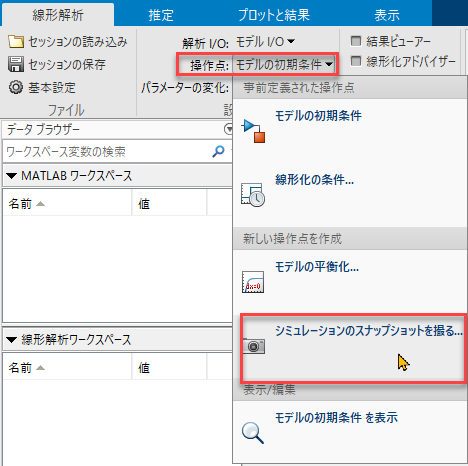

**2.2.3　微分方程式のシミュレーション**で確認したシミュレーション結果から

0.03秒以降であれば十分解が一意の値に収束してい良う見えるので

今回はスナップショット時間を0.03と設定した。

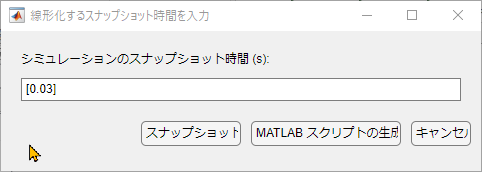

スナップショットボタンをクリックすると

線形化アプリ専用のローカルワークスペースである

線形解析ワークスペースにop_snapshot1というデータが追加される。

アプリ上部の「ステップ、ボード線図、インパルス、ナイキスト、ニコルス線図・・・」等のプロットをクリックすれば

アプリが定常解近傍での線形化を実施し、指定したグラフをプロットする。

プロット画面右端の▽ボタンをクリックすることですべての操作ボタンを閲覧できる。

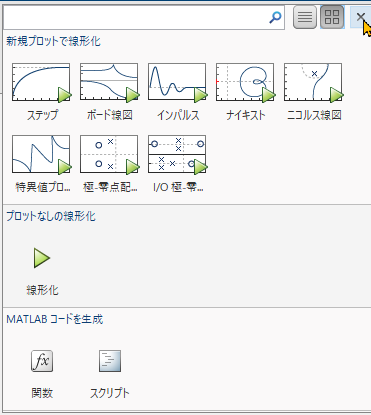

ここで「ボード線図」をクリックすると下記の通り取得ができた。

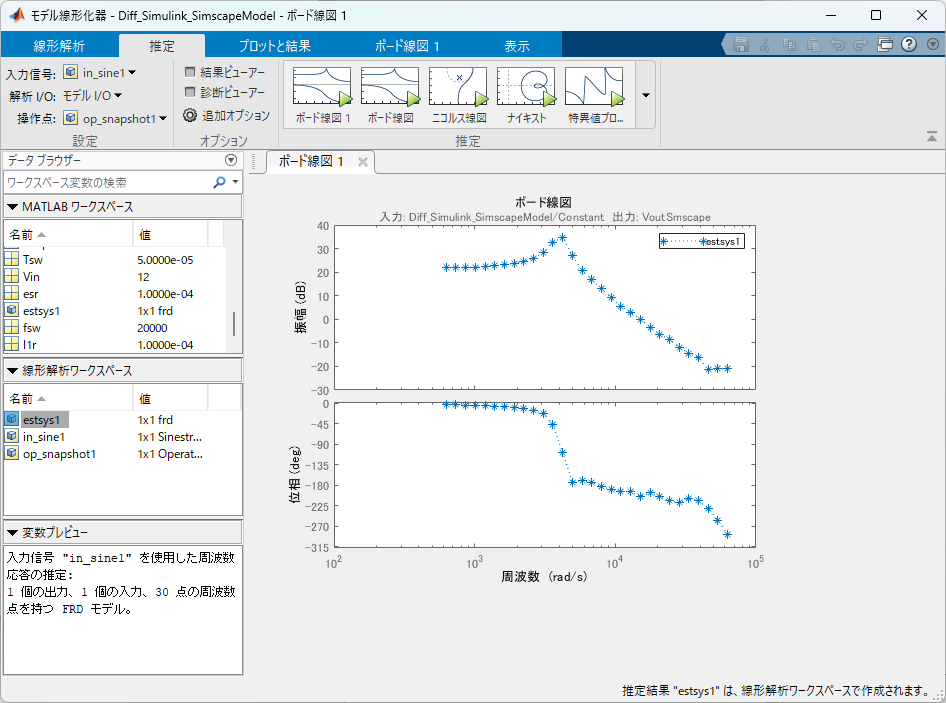

モデルのシミュレーション結果をScopeで観測しても、段階的に周波数を切り替えながらDutyを変化させ、その影響が電流および電圧にあらわれていることが見て取れる。

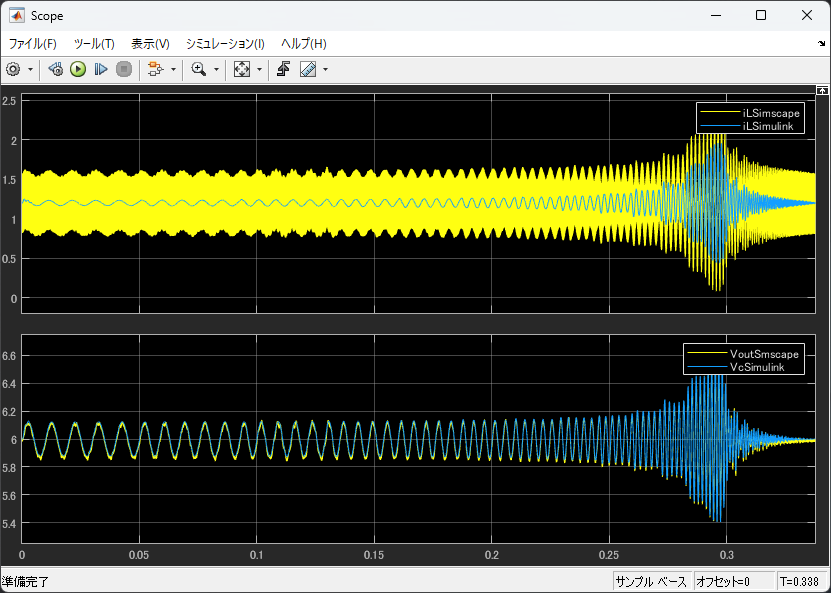

#### APIでの実行

上記操作はAPIから操作することもできる

%解析対象のモデル名を指定します
mdlName = 'Diff_Simulink_SimscapeModel'

mdlName = 'Diff_Simulink_SimscapeModel'

%スナップショットを取得しシミュレーション経過時間0.03秒時点での各状態情報を取得します
op = findop(mdlName,0.03);

%getlinio関数でモデルで指定されている線形解析ポイントのデータを取得します。
ios = getlinio(mdlName);

%logspace関数で対数刻みでの周波数セットデータを作成します
fmin = 100; %周波数最小値
fmax = 50000;%周波数最大値
num_f = 30;%周波数の数
f = logspace(log10(fmin),log10(fmax),num_f);

%frest.Sinestream関数で周波数セットを作成します
in = frest.Sinestream('Frequency',f,'Amplitude',0.01,'NumPeriods',4,...
                      'SettlingPeriods',1,'RampPeriods',0,'SamplesPerPeriod',40);

%frestimate関数を用いて周波数推定解析を開始します。
%1つ目の戻り値に推定された離散周波数データ、2つ目の戻り値にシミュレーションログが返されます。
[estsys1,simlog] = frestimate(mdlName,op,ios,in);


### 操作５:代数式演算の結果と比較

Script02で求めたSymbolic式データをロードする。

load('SymbolicEquation.mat');

アプリで線形化された結果は

線形化アプリ専用のローカルワークスペースである

線形解析ワークスペースにop_snapshot1というデータが追加される。

こちらをMATLABワークスペースにドラッグ・アンド・ドロップすれば、データが

MATALBのワークスペースにコピーされてスクリプトから操作できるようになる。

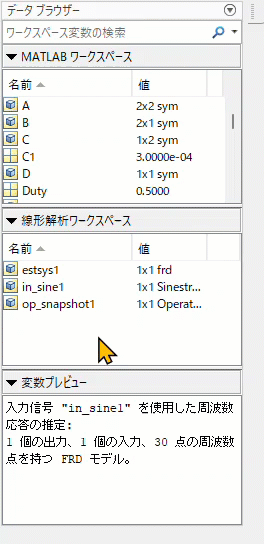

**コピーされた変数名が”estsys1"以外ならば下記スクリプトの都合上名前を"estsys1"にリネームすること。**

**そのデータが無いとこの後のスクリプトはエラーで止まってしまいます。**

代数式モデルとアプリで取得した線形化結果を比較する。結果は概ね理論と一致している。

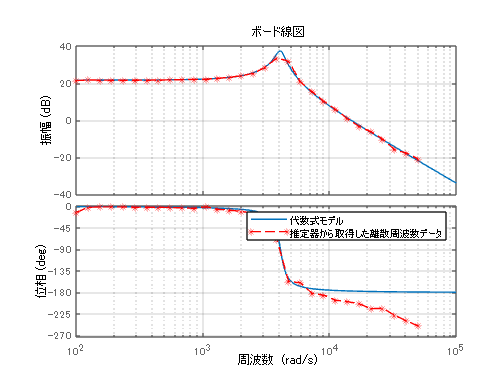

%Symbolic式を伝達関数モデルに変換
Gplant_s = arrayfun(@sym2tf_ykamatan,subs(GdXdDuty),'UniformOutput',false);

%各要素のボード線図を描画
figure;
bodeplot(Gplant_s{2,1});
grid on;
hold on;
bodeplot(estsys1,'--*r');

legend('代数式モデル','推定器から取得した離散周波数データ')

高周波領域で位相特性が一致していない部分についてはむだ時間遅れの影響が理論モデルには反映されていない一方

Simscapeモデル側はPWMによるスイッチングの挙動含めてモデリングがされているため、

Duty値の更新とパルス反映までのむだ時間が表現されておりその影響が現れている。

PWMのスイッチング周期を$T_{\textrm{sw}}$とするとむだ時間の影響は


$$G_{\textrm{delay}} \left(s\right)=e^{-{\textrm{sT}}_{\textrm{sw}} } \;$$


である。

これは外乱の影響における最悪値を示している。

すなわちPWMデューティを更新した直後に外乱が発生した場合、その反映は最大Tsw時間経過したあとになることを示している。

そのため、外乱の発生タイミングに応じてこのむだ時間は変化することになる。

ここで外乱の発生タイミングが一様にばらついていると想定すると、平均的には遅延時間$\frac{1}{2}T_{\textrm{sw}}$となるはずである。

そのため実際には実機での計測結果も概ね下記式に従う。


$$G_{\textrm{delay}} \left(s\right)=e^{-{s\;\frac{1}{2}T{\textrm{sw}} } } \;$$


**＃注意事項として実機やシミュレーションの計測結果と一致させる目的であれば**$\frac{1}{2}T_{\textrm{sw}}$**が概ね妥当であるが、設計の最悪値としてはむだ時間を**$T_{\textrm{sw}}$**とするのが最も保守的な設計である。**

下記コードでボード線図の一致性を確認する。結果からも位相の遅れはむだ時間による影響である可能性が高いとうかがえる。

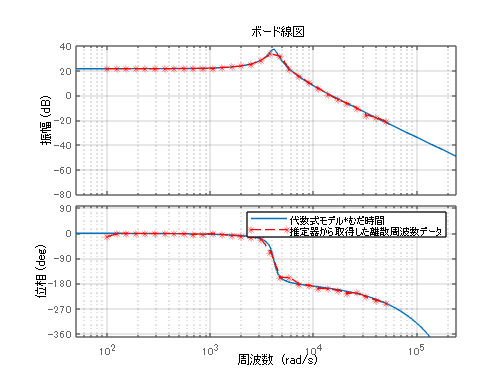

load('SymbolicEquation.mat');
%Symbolic式を伝達関数モデルに変換
Gplant_s = arrayfun(@sym2tf_ykamatan,subs(GdXdDuty),'UniformOutput',false);

s = tf('s');
Gdelay = exp(-s*Tsw*0.5);

%各要素のボード線図を描画
figure;
bodeplot(Gplant_s{2,1}*Gdelay);
grid on;
hold on;
h =bodeplot(estsys1,'--*r');
legend('代数式モデル*むだ時間','推定器から取得した離散周波数データ')
p = getoptions(h);
p.XLim = {[50, 240000]};
p.YLim = {[-80, 40];[-370, 100]};
setoptions(h,p);

### 操作6.　離散値としての周波数データから連続系の伝達関数への変換

今回の例では取得したデータを離散データのままPlotしていますが、

この離散データにフィットする連続の伝達関数モデルを推定したい場合は　

System Identification Toolboxが提供する [tfes](https://jp.mathworks.com/help/ident/ref/tfest.html)t関数を用いることで

推定した周波数特性離散データに最大限一致する連続系伝達関数の係数値を推定が可能です。

第一引数に 今回推定した周波数特性の離散データが格納されている”estsys1”を指定し、

第二引数にフィッティングしたい伝達関数の極数、

第三引数にフィッティングしたい伝達関数の零点数を入力します。

もし、むだ時間を含めて推定結果を出したい場合は第四引数にむだ時間を指定します。

estTf = tfest(estsys1,3,1,Tsw/2)

estTf =
  入力 "Diff_Simulink_SimscapeModel/Constant" から出力 "VoutSmscape":
                             2.989e08 s - 2.08e12
  exp(-2.5e-05*s) * --------------------------------------
                    s^3 - 9064 s^2 + 8.227e06 s - 1.743e11
 
同定された連続時間伝達関数です。

パラメーター化:
   極の数: 3   零点の数: 1
   自由係数の数: 5
   パラメーターとその不確かさについては、"tfdata"、"getpvec"、"getcov" を使用してください。

状態:                                     
周波数応答データ "estsys1" に TFEST を使用して推定されました。
推定データへの適合: 86.77%                       
FPE: 4.807, MSE: 3.434                  
 
モデル プロパティ


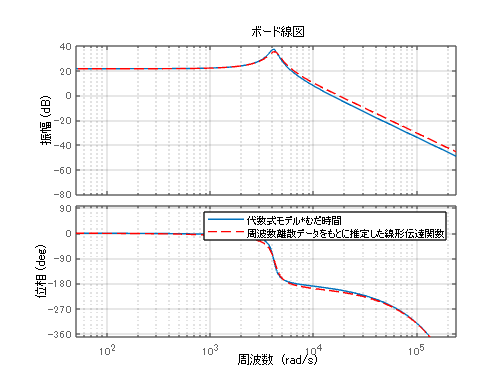


figure;
bodeplot(Gplant_s{2,1}*Gdelay);
grid on;
hold on;
h =bodeplot(estTf,'--r');
legend('代数式モデル*むだ時間','周波数離散データをもとに推定した線形伝達関数')
p = getoptions(h);
p.XLim = {[50, 240000]};
p.YLim = {[-80, 40];[-370, 100]};
setoptions(h,p);

上記の通り、代数式モデルともよく一致する連続系伝達関数がSimscapeの回路モデルから取得できることがわかります。

このアプローチは新規で回路トポロジーを検討する際に、理論上の伝達関数が求まらない場合、

Simulation上でのデータをベースとして伝達関数を推定する必要があるときに有効なアプローチとなります。

**Simulinkは状態平均化法による立式といった理論ベースのモデリングについても、**

**今回ご紹介したデータに基づくデータドリブンなモデリングについても同一環境で遂行が可能です。**

**そのため、お客様の開発の目的に応じて柔軟に対応できるツールになっています。**

こちらの機能の使用等詳細な情報はヘルプドキュメントをご確認くださいませ。

#### コマンド ラインでの伝達関数モデルの推定(EN)

[https://jp.mathworks.com/help/ident/ug/how-to-estimate-transfer-function-models-at-the-command-line.html](https://jp.mathworks.com/help/ident/ug/how-to-estimate-transfer-function-models-at-the-command-line.html)

#### 与えられた周波数応答データに適合する伝達遅延をもつ伝達関数モデルの推定(EN)

[https://jp.mathworks.com/help/ident/ug/estimate-transfer-function-models-with-transport-delay-to-fit-given-frequency-response-data.html](https://jp.mathworks.com/help/ident/ug/estimate-transfer-function-models-with-transport-delay-to-fit-given-frequency-response-data.html)

#### 昇圧コンバーター向け伝達関数モデルの推定

[https://jp.mathworks.com/help/ident/ug/estimating-transfer-function-models-for-a-boost-converter.html](https://jp.mathworks.com/help/ident/ug/estimating-transfer-function-models-for-a-boost-converter.html)